[audio, fs] = audioread('instru1.wav');
f1 = pitch(audio,fs)

f1 =   262.5000
  262.5000
  262.5000
  262.5000
  262.5000
  262.5000
  262.5000
  262.5000
  262.5000
  262.5000


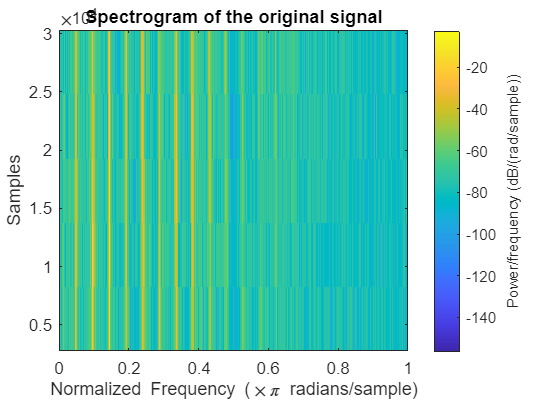


figure(1);
spectrogram(audio, fs);
title('Spectrogram of the original signal');

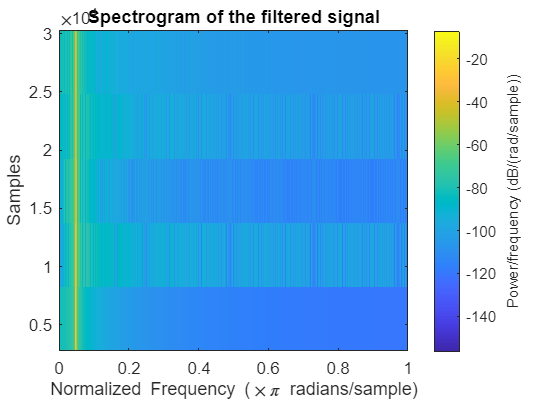


f0  = 262.5;
fcut = [f0 - 10, f0 + 10]; 
order = 4; 
[b, a] = butter(order, fcut/(fs/2), 'bandpass');

filtered_audio = filter(b, a, audio);

figure(2);
spectrogram(filtered_audio, fs);
title('Spectrogram of the filtered signal');


audiowrite('instru1_filtered.wav', filtered_audio, fs);

soundsc(filtered_audio, fs);